# System of Simultaneous Linear Equations

- Gauss Elimination

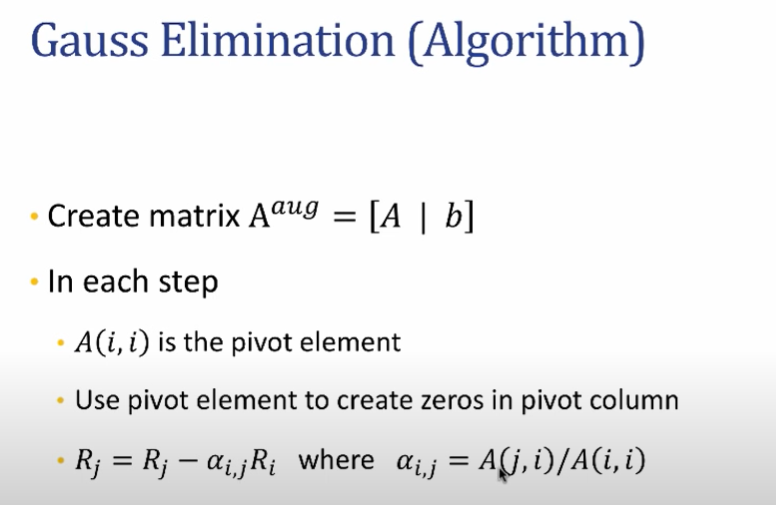

Note - Determinant of A should not be **zero**

clc;
clear;
format short;
tic();
A = [ 20 1 1; 3 20 3; 1 4 30];
B = [10; 15 ; 16];
if(det(A)==0)
    disp('Determinant is 0, so unable to proceed')
    return;
end

answer = A\B;

aug = [A,B]; % Augmented Matrix

n = length(A)

n = 3

for i = 1:n-1
    fprintf('i=%d,',i)
    for j = 1:(n-i)
        if(aug(i,i)==0)
            disp(' Divided by 0 Error was coming thats why, I returned from here ');
            return; % This is added 
        end
        alpha = aug(j+i,i)/aug(i,i);
        aug(j+i,:) = aug(j+i,:) - alpha*aug(i,:);
    end
end

i=1,i=2,


disp(aug); % Converted into upper triangular Matrix

   20.0000    1.0000    1.0000   10.0000
         0   19.8500    2.8500   13.5000
         0         0   29.3829   12.8136




% Doing Backsubstitution

xvalues(1:length(A)) = 0; % Creates X values
xvalues = xvalues';
for i = 1:length(xvalues)
    index = length(xvalues)-i+1;
    xvalues(index) = (aug(index,end) - aug(index,index:length(xvalues))*xvalues(index:length(xvalues)))/aug(index,index);
end

disp('Final Values = ')

Final Values = 


disp(xvalues);

    0.4473
    0.6175
    0.4361



disp('Correct Ans = ');

Correct Ans = 


disp(answer);

    0.4473
    0.6175
    0.4361



toc();

Elapsed time is 0.051550 seconds.


## Some Issues with Gauss Elimination Method

- Division by Zero 

- Round off Errors

**Division by Zero**

This can happen if one of the diagonal elements become zero, in intermediate stage while on which the division was going on, so it will generate Division by Zero Error

**Round Off Errors**

## Gauss Jordan Method

clc;
clear;
format short;
tic();
A = [ 20 1 1; 3 20 3; 1 4 30];
B = [10; 15 ; 16];

if(det(A)==0)
    disp('Determinant is 0, so unable to proceed')
    return;
end


aug = [A,B]; % Augmented Matrix

n = length(A)

n = 3

for i = 1:n-1
    fprintf('i=%d,',i)
    for j = 1:(n-i)
        if(aug(i,i)==0)
            disp(' Divided by 0 Error was coming thats why, I returned from here ');
            return; % This is added 
        end
        alpha = aug(j+i,i)/aug(i,i);
        aug(j+i,:) = aug(j+i,:) - alpha*aug(i,:);
    end
end

i=1,i=2,


disp(aug); % Converted into upper triangular Matrix

   20.0000    1.0000    1.0000   10.0000
         0   19.8500    2.8500   13.5000
         0         0   29.3829   12.8136








for i=1:length(A)-1
    for j=i:length(A)-1
        % j as row
        % i as column
        fprintf('i=%d,j=%d\n',n-j,n-i+1);
        a = n-j;
        b = n-i+1;
        fprintf('--------------------------');
        
        disp(aug)
        

        alpha = aug(a,b)/aug(b,b);
        aug(a,:) = aug(a,:) - alpha*aug(b,:);
    end
    
end

i=2,j=3


--------------------------

   20.0000    1.0000    1.0000   10.0000
         0   19.8500    2.8500   13.5000
         0         0   29.3829   12.8136



i=1,j=3


--------------------------

   20.0000    1.0000    1.0000   10.0000
         0   19.8500         0   12.2571
         0         0   29.3829   12.8136



i=1,j=2


--------------------------

   20.0000    1.0000    0.0000    9.5639
         0   19.8500         0   12.2571
         0         0   29.3829   12.8136




fprintf('--------------------------');

--------------------------

disp(aug)

   20.0000         0    0.0000    8.9464
         0   19.8500         0   12.2571
         0         0   29.3829   12.8136




xvalues(1:length(A)) = 0;
xvalues = xvalues';
for i=1:n
    xvalues(i) = aug(i,end)/aug(i,i);
end


toc();

Elapsed time is 0.065296 seconds.



answer = A\B;

disp('Final Values = ')

Final Values = 


disp(xvalues);

    0.4473
    0.6175
    0.4361



disp('Correct Ans = ');

Correct Ans = 


disp(answer);

    0.4473
    0.6175
    0.4361

